# TASK 1 Preparation 

### 1) Hough transform

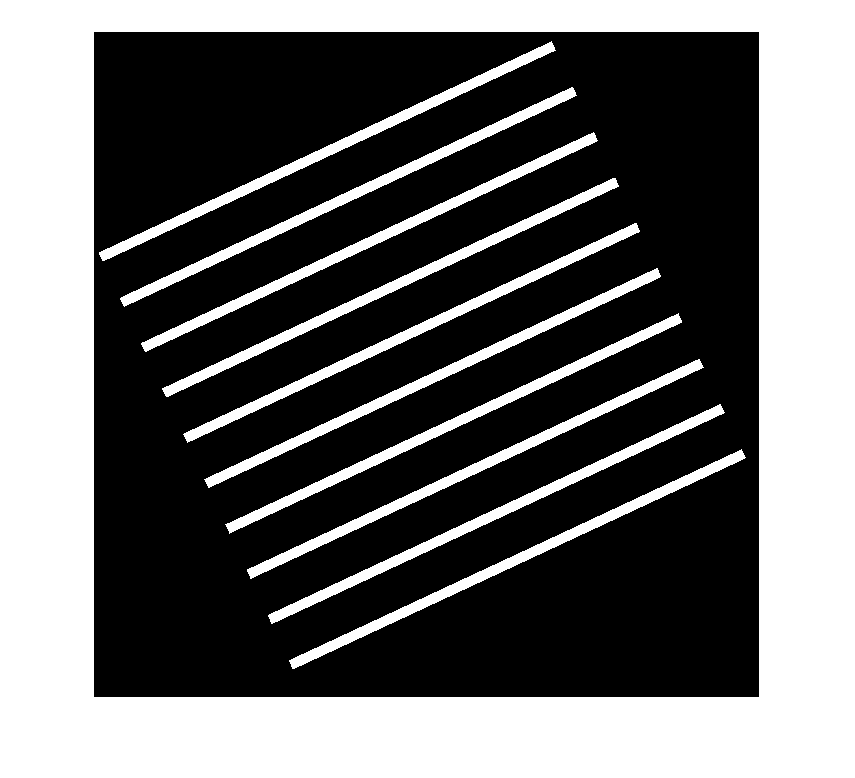

im1a = imread("images\Image1a.tif");
im1b = imread("images\Image1b.tif");

imshow(im1a)

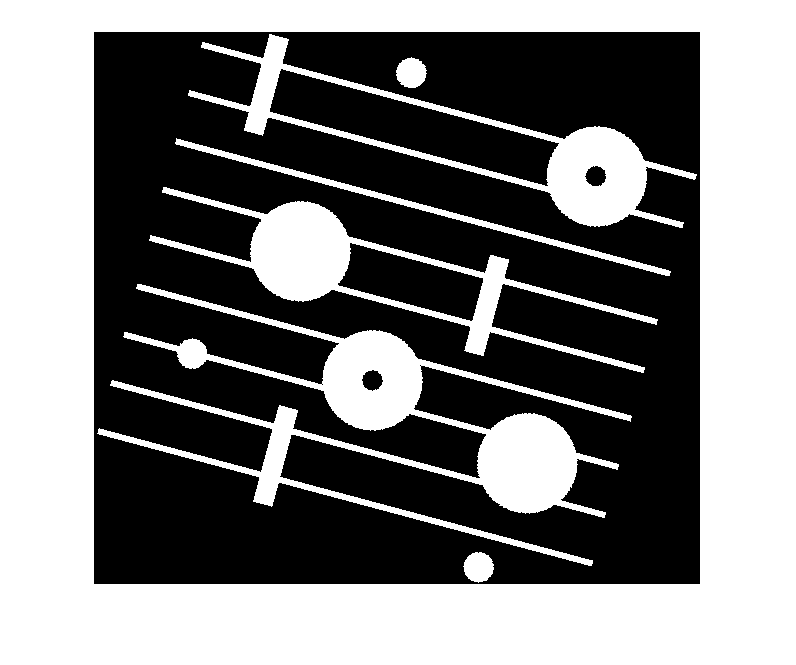

imshow(im1b)


[H, teta, ro] = hough(im1a, 'Rhoresolution',5,'Theta',-90:0.5:89.5); 

% contrast stretching to scale [0,1]
maxV = max(H(:));
minV = min(H(:));

H1 = (H-minV)/(maxV-minV)

H1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

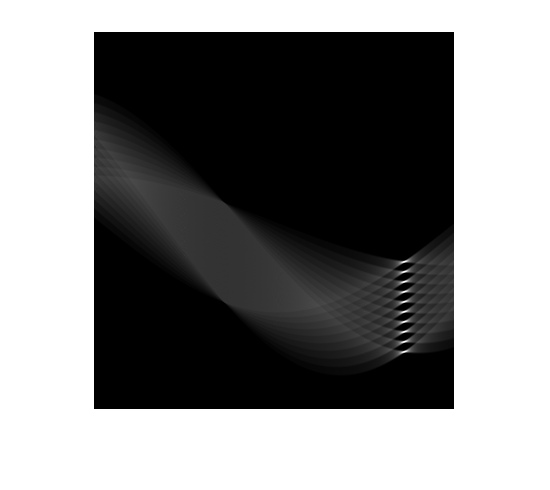

imshow(H1)

imwrite(H1, 'images\H1.png')

% Problem 3
[r,t] = find(H==max(H(:)));
angle = teta(t(1))

angle = 65

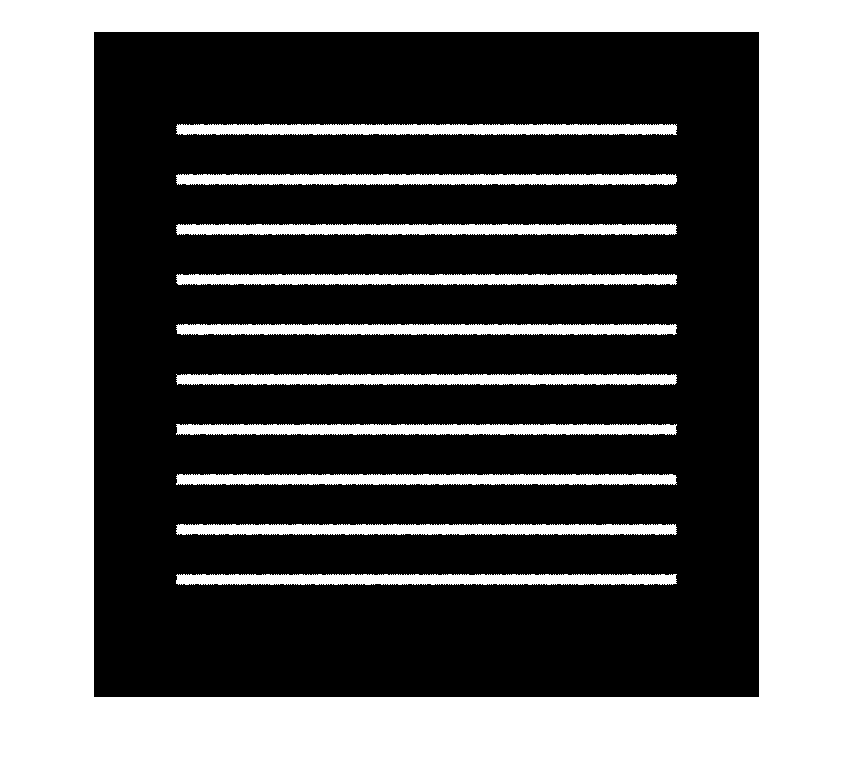


% Problem 5
Image1a_rotated = imrotate(im1a,-25,'bicubic', 'crop');
imshow(Image1a_rotated);

imwrite(Image1a_rotated, 'images\Image1a_rotated.png');


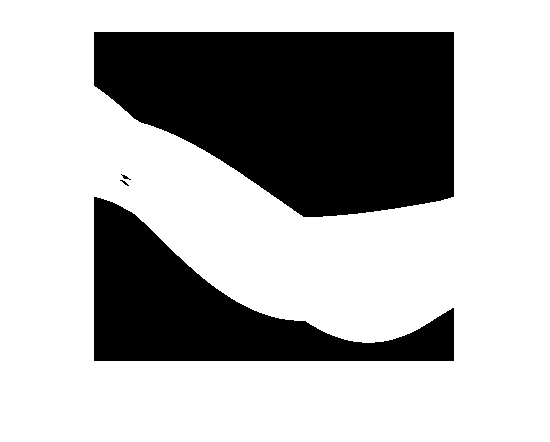

% Image1b
im1b = imread("images\Image1b.tif");

[H, teta, ro] = hough(im1b, 'Rhoresolution',5,'Theta',-90:0.5:89.5); 
imshow(H)

% problem 6

[r,t] = find(H==max(H(:)));
teta(t(1))

ans = -75

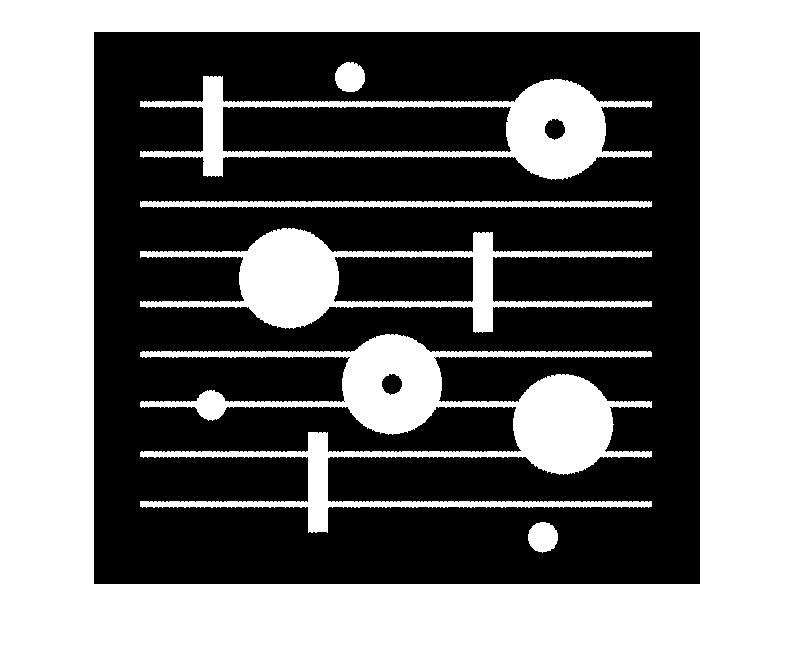


% Problem 7
Image1b_rotated = imrotate(im1b,15,'bicubic', 'crop');
imshow(Image1b_rotated);

imwrite(Image1b_rotated, 'images\Image1b_rotated.png');


### 2) Morphology

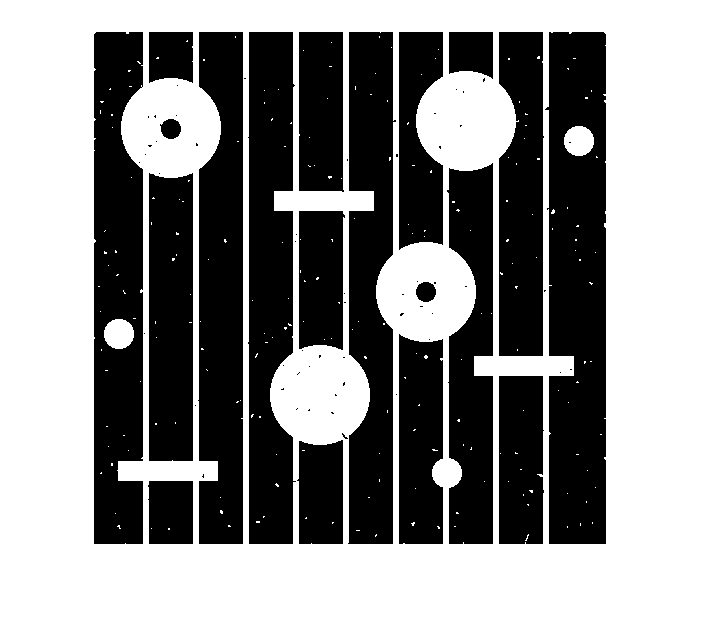

im1c = imread("images\Image1c.tif");
imshow(im1c)

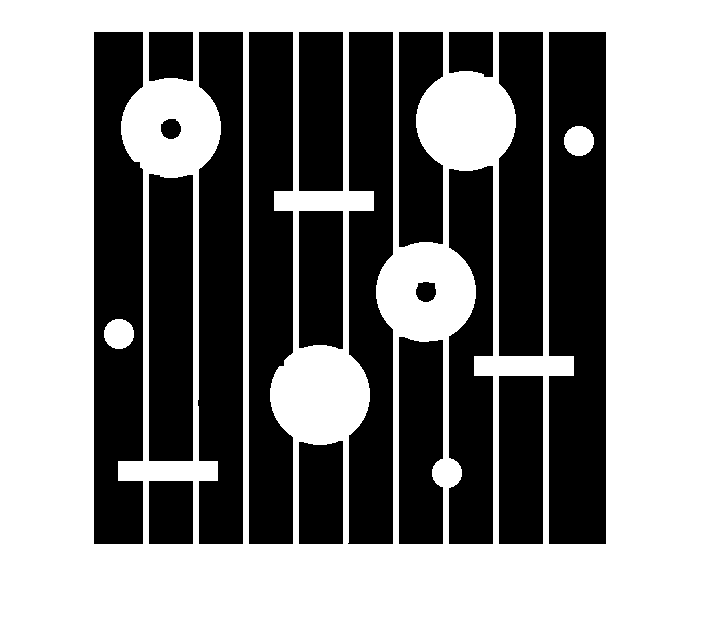


% Problem 9
% Structuring element
r=3; % Radius
SE = strel('disk',r);

% Morphological openig and closing for noise
im2c = imopen(im1c,SE);
im3c = imclose(im2c,SE);
imshow(im3c)

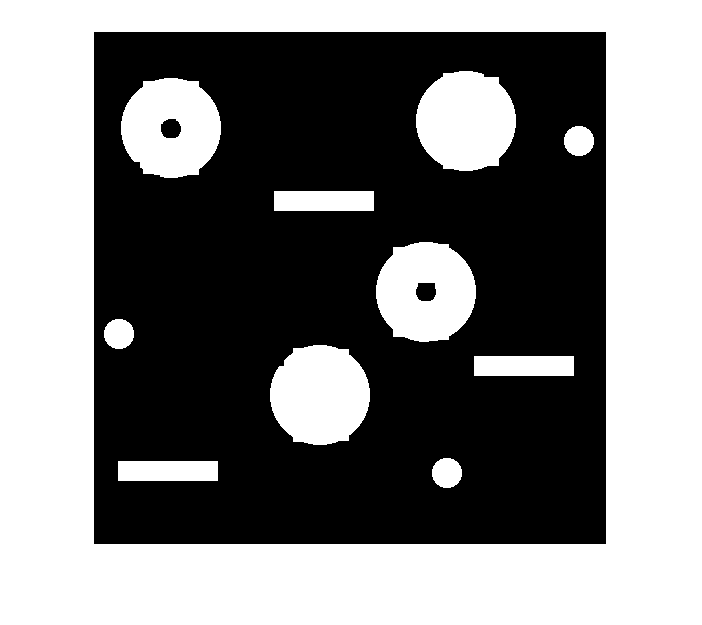

imwrite(im3c, "images\1cNoNoise.png");

% Problem 10
% Remove lines
len = 6;
deg = 0; 
SE = strel('line', len, deg);

% Morphological openig and closing for noise
im2c = imopen(im3c,SE);
Image1c_clean = imclose(im2c,SE);
imshow(Image1c_clean)

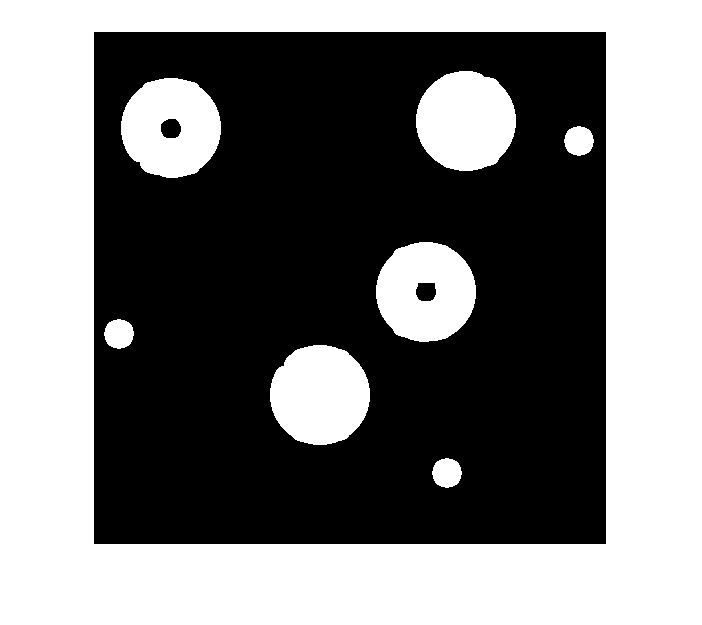

imwrite(Image1c_clean, "images\Image1c_clean.png");

% Problem 11a
% Remove rectangles
SE = strel('disk',10,0);
imDiscs = imopen(Image1c_clean,SE);
% im11a2 = imclose(im11a,SE);
imshow(imDiscs)

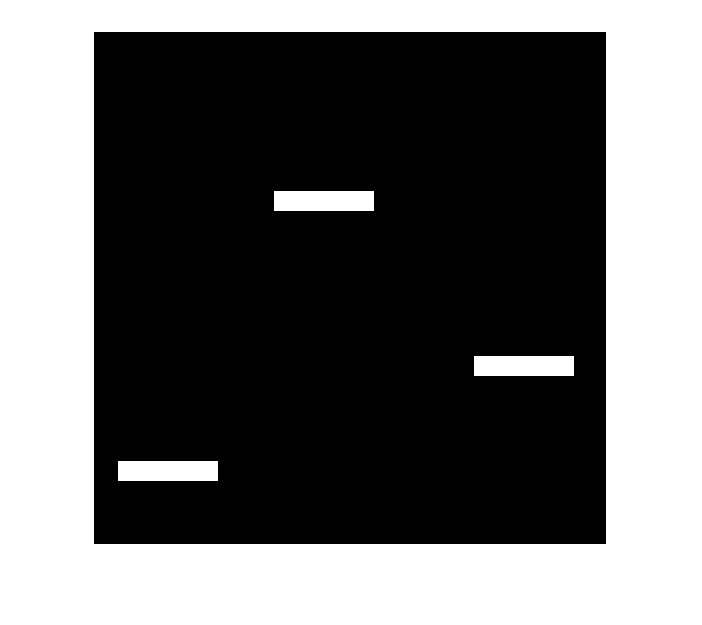


% Problem 11b - only rectangles
MN = [20 100];
SE = strel('rectangle',MN);
imRectangles = imopen(Image1c_clean,SE);
% im11b2 = imclose(im11b,SE);
imshow(imRectangles)

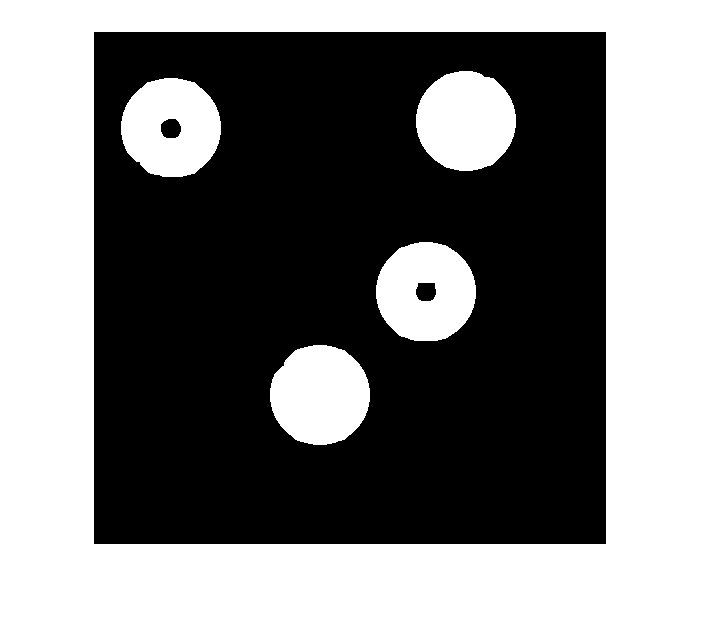


% Problem 11c - only large diskcss
SE = strel('disk',15);
imLargeDiscs = imopen(imDiscs,SE);
% im11b2 = imclose(im11b,SE);
imshow(imLargeDiscs)


imSmallDiscs =  imDiscs - imLargeDiscs;
% Problem 11d - RGB-image
[r,c] = size(im1c);
RGB = zeros(r,c,3)

RGB = RGB(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

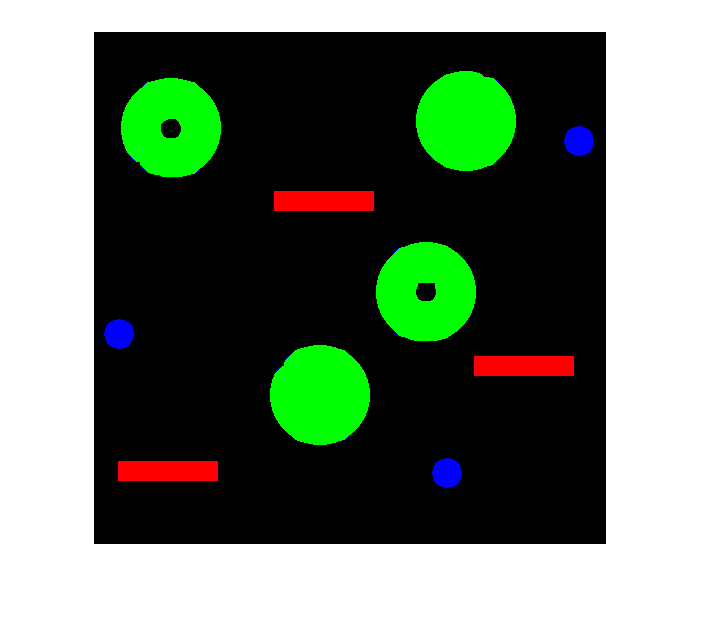

RGB(:,:,1) = imRectangles;
RGB(:,:,2) = imLargeDiscs;
RGB(:,:,3) = imSmallDiscs;
imshow(RGB)

imwrite(RGB, "images\RGB.png");

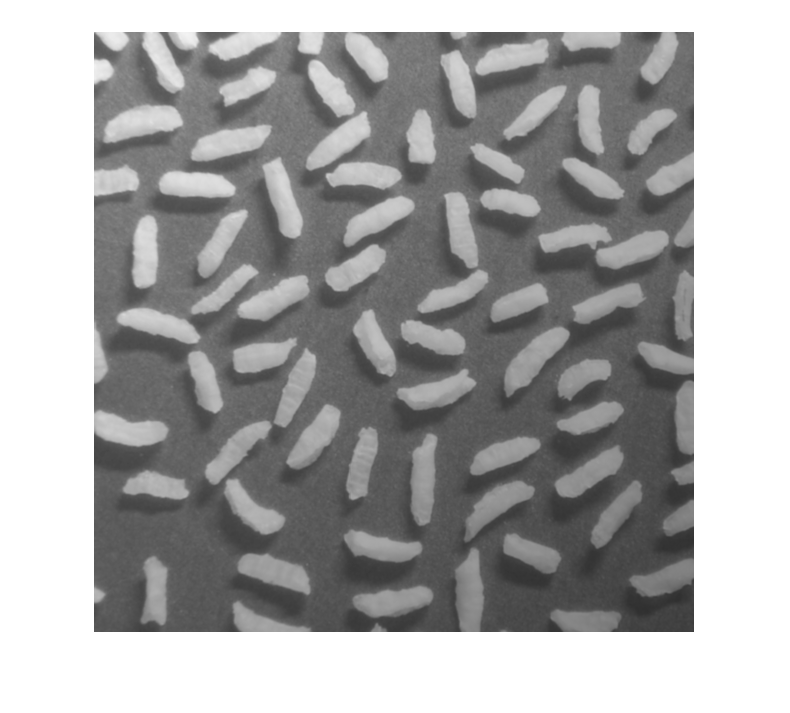

% Problem 12
imRice = imread("images\rice-shaded.tif");
imRice = im2double(imRice);

imshow(imRice)

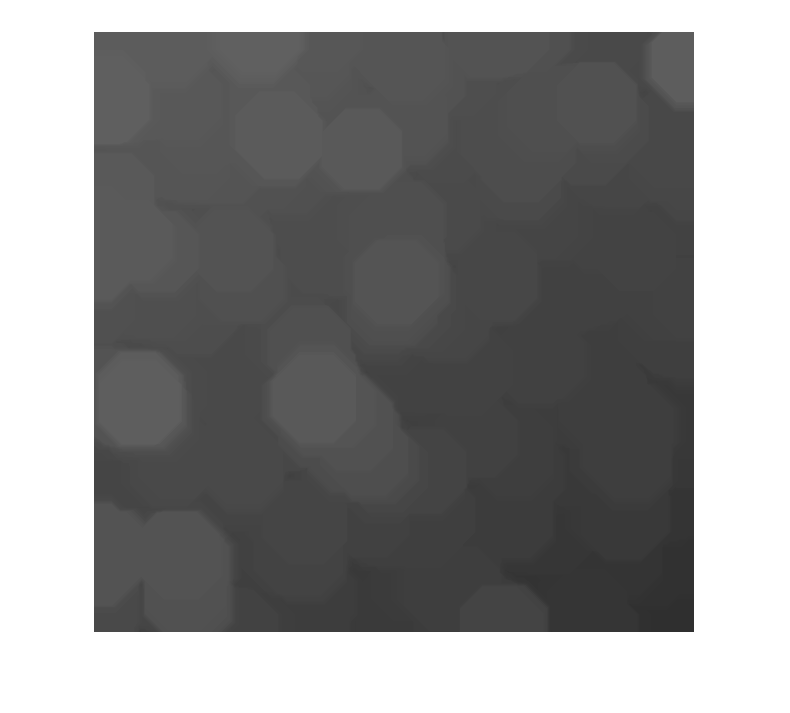

SE = strel('disk', 40);

im12a = imopen(imRice,SE);
% im12b = imclose(im12a,SE);
imshow(im12a)

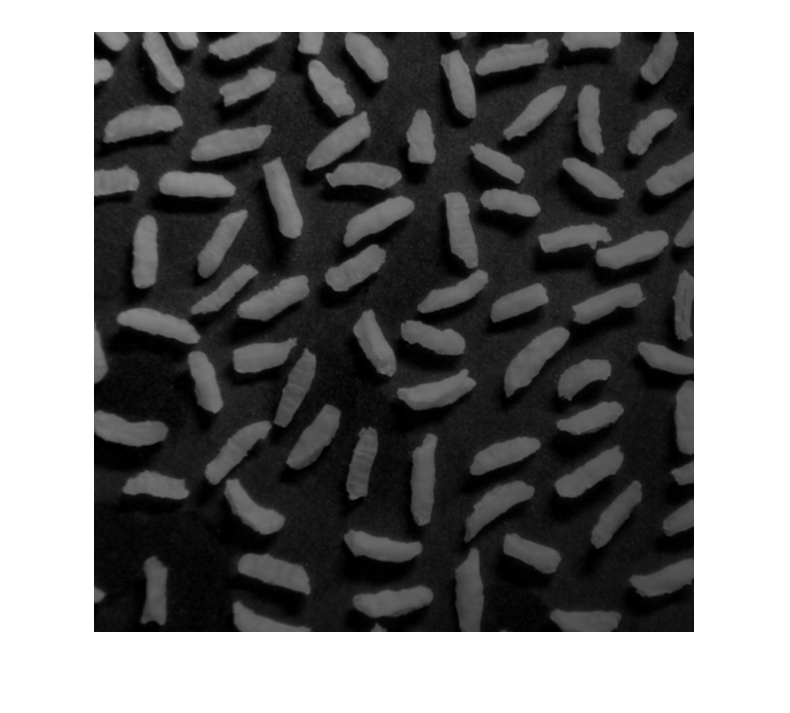

% imshow(im12b)

tophat = imRice - im12a;
imshow(tophat);

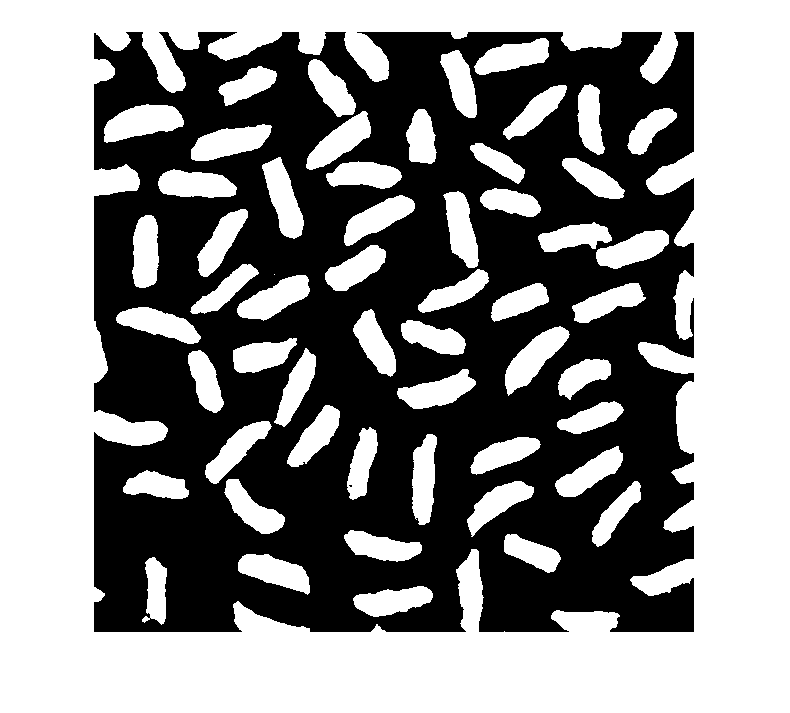


level = graythresh(tophat);% computes a global threshold using Otsu's method

r_thresh = tophat>level; 
imshow(r_thresh)

imwrite(r_thresh, "images\r_thresh.png")

### 3) Labelling and object features

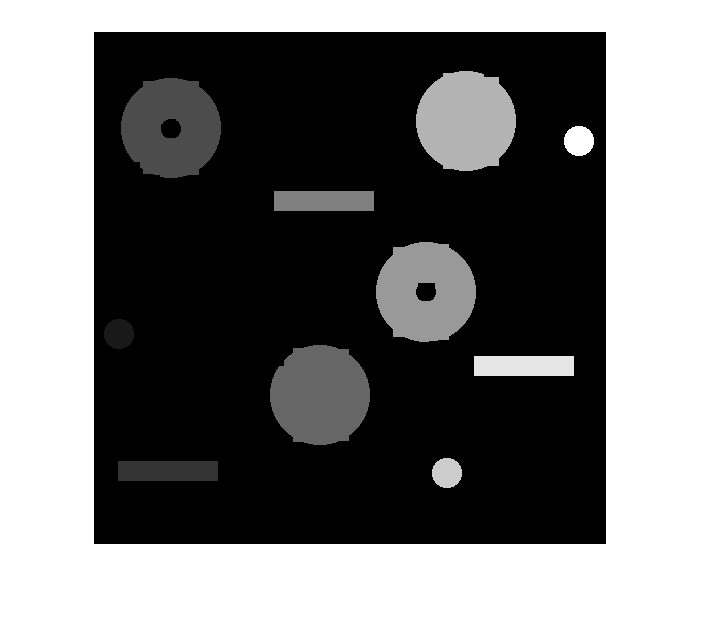

% Problem 13
L = bwlabel(Image1c_clean);
imshow(L,[])

%L = mat2gray(L);
imwrite(L, "images\im13.png");

% Problem 14
S = regionprops(L, 'Perimeter','Area', 'EulerNumber')

S = 10×1 struct array with fields:
    Area
    EulerNumber
    Perimeter



% Matrices for all objects
for n=1:length(S)
    Perimeter(n)=S(n).Perimeter;
    Area(n)=S(n).Area;
    Euler(n)=S(n).EulerNumber;
end
Euler

Euler =      1     1     0     1     1     0     1     1     1     1


Area

Area =          717        2000        7622        7934        2000        7642        7944         716        2000         716



% Find all objects larger than 3000 pixels
LargeO = find(Area>3000)

LargeO =      3     4     6     7


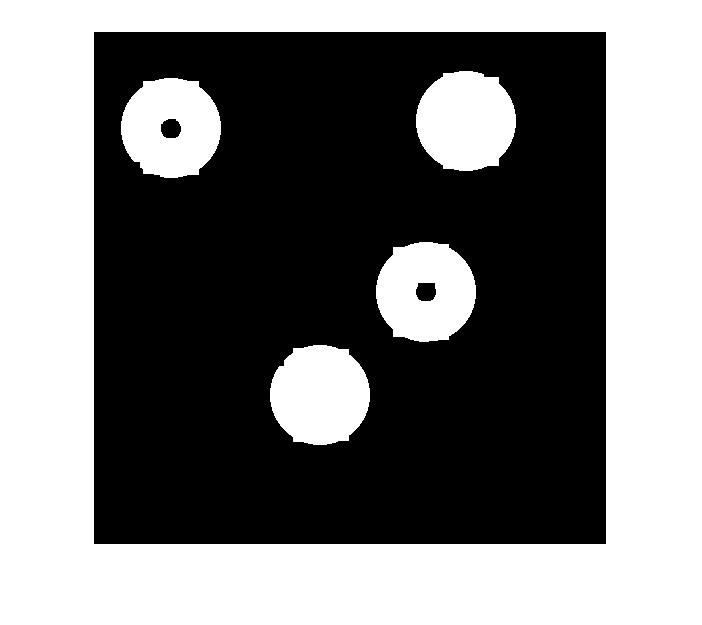


% Perimeter for all large objects
% Perimeter(LargeO)

% Image containing only the large objects
LargeO_Im = zeros(r,c); % creates an empty matrix
for n=1:length(LargeO) % number of large objects
    LargeO_Im(L==LargeO(n))=1; % Large object area is set to 1
end
imshow(LargeO_Im)

imwrite(LargeO_Im, "images\LargeO_Im.png");

% Problem 15
Perimeter

Perimeter =    92.3120  230.9160  327.4740  325.6300  230.9160  324.3400  324.9850   92.3120  230.9160   92.3120


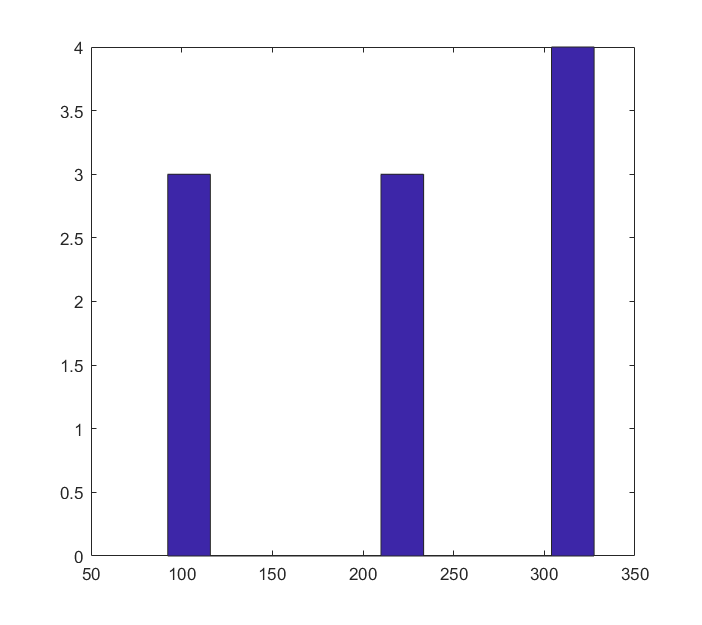

hist(Perimeter)

SmallO=find(Perimeter<150)

SmallO =      1     8    10



Perimeter1 = Perimeter(SmallO)

Perimeter1 =    92.3120   92.3120   92.3120


Area1 = Area(SmallO)

Area1 =    717   716   716


Euler1 = Euler(SmallO)

Euler1 =      1     1     1



% Problem 16
Objects = find(Area > 3000 & Euler < 1)

Objects =      3     6


Area2 = Area(Objects)

Area2 =         7622        7642


Euler2 = Euler(Objects)

Euler2 =      0     0


Per2 = Perimeter(Objects)

Per2 =   327.4740  324.3400


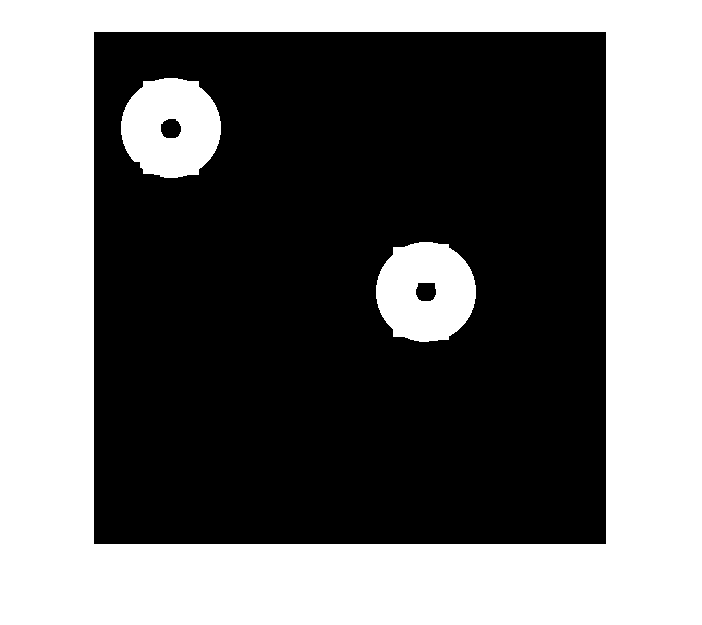


Object_Im = zeros(r,c);
for n=1:length(Objects) % the number of large objects
 Object_Im(L==Objects(n))=1; % Large object area is set to 1
end
imshow(Object_Im)

imwrite(Object_Im, "images\Object_Im.png")